# 基于不同滤波实现主动降噪功能

## 1.读取信号

clc;
clear;

### 1.1.读取mp3文件为离散信号

mp3file = '';
[y, fs] = audioread(mp3file);
music = y(:,1);
% 这里读取的y为双声道的信号,fs为采样率
% 读取左声道,进行后续分析(右声道亦可)
N = length(music);

### 1.2.绘制波形

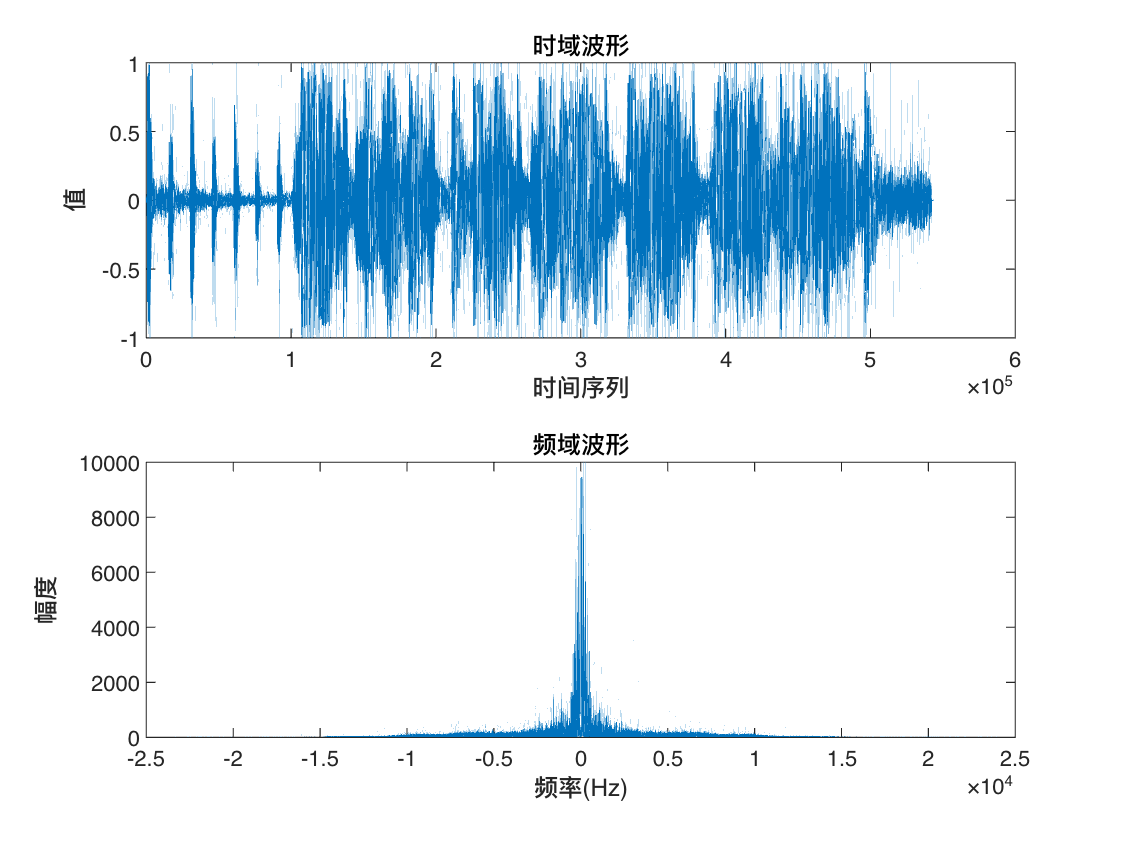

f = linspace(-fs/2,fs/2,N);
figure("NumberTitle","off","Name","mp3_file");
subplot(211);
plot(music),title("时域波形");
xlabel("时间序列");
ylabel("值");
subplot(212);
plot(f,abs(fftshift(fft(music)))),title("频域波形");
xlabel("频率(Hz)");
ylabel("幅度");

### 1.3.播放声音

% sound(music,44100);

## 2.模拟噪声下的去噪算法

### 2.1.生成模拟噪声(randn为例)

simulated_noise = 0.4 * randn(length(music),1);
simulated_noise_music = simulated_noise + music;

### 2.2.绘制噪声信号

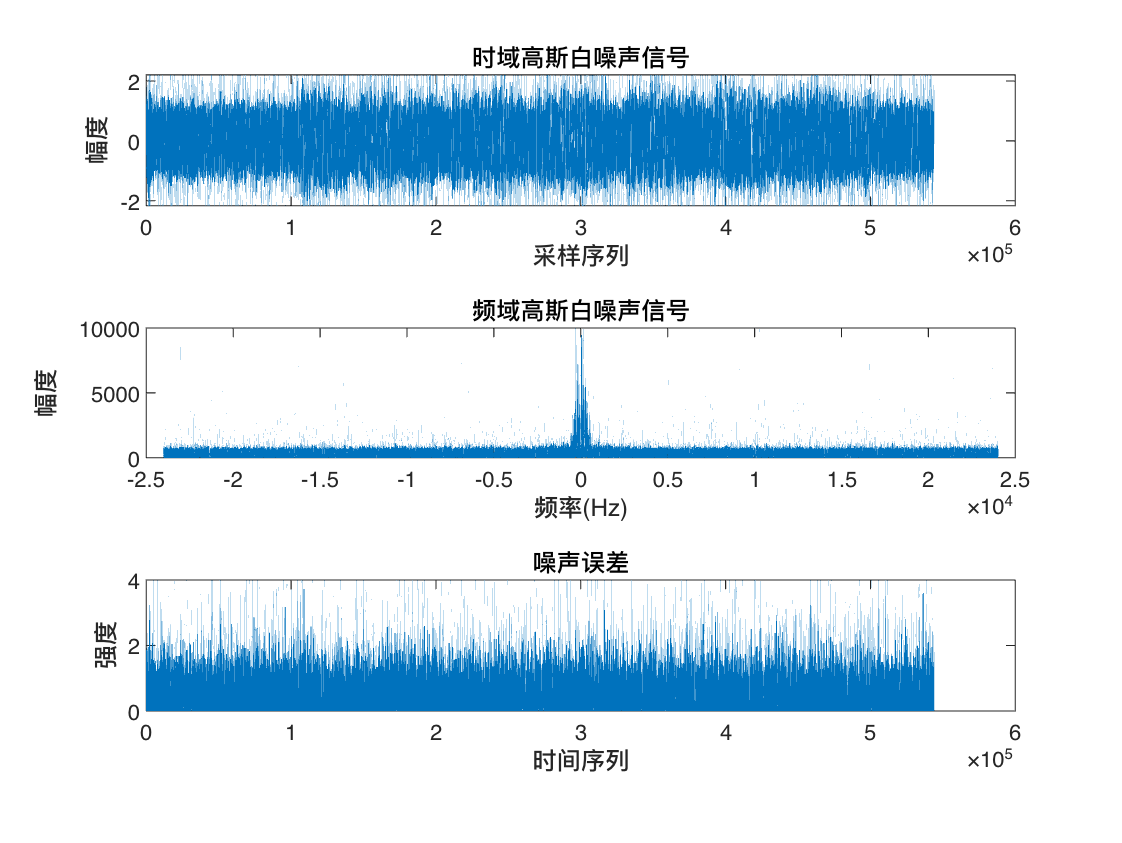

figure("NumberTitle","off","Name","高斯白噪声");
subplot(311);
plot(simulated_noise_music);
xlabel('采样序列');
ylabel('幅度');
title('时域高斯白噪声信号');
subplot(312);
plot(f,abs(fftshift(fft(simulated_noise_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频域高斯白噪声信号");
en_noise_simulated = (simulated_noise_music - music) .^ 2;
subplot(313);
plot(en_noise_simulated);
xlabel("时间序列");
ylabel("强度");
title("噪声误差");

### 2.3.播放效果

% sound(simulated_noise_music,44100);

### 2.4.FIR滤波器

%% 设计低通滤波器
fir_filter = fir1(64, 0.02, 'low');
%% 应用低通滤波器
simulated_fir_filtered_music = filter(fir_filter, 1, simulated_noise_music);

### 2.5.FIR滤波器效果展示

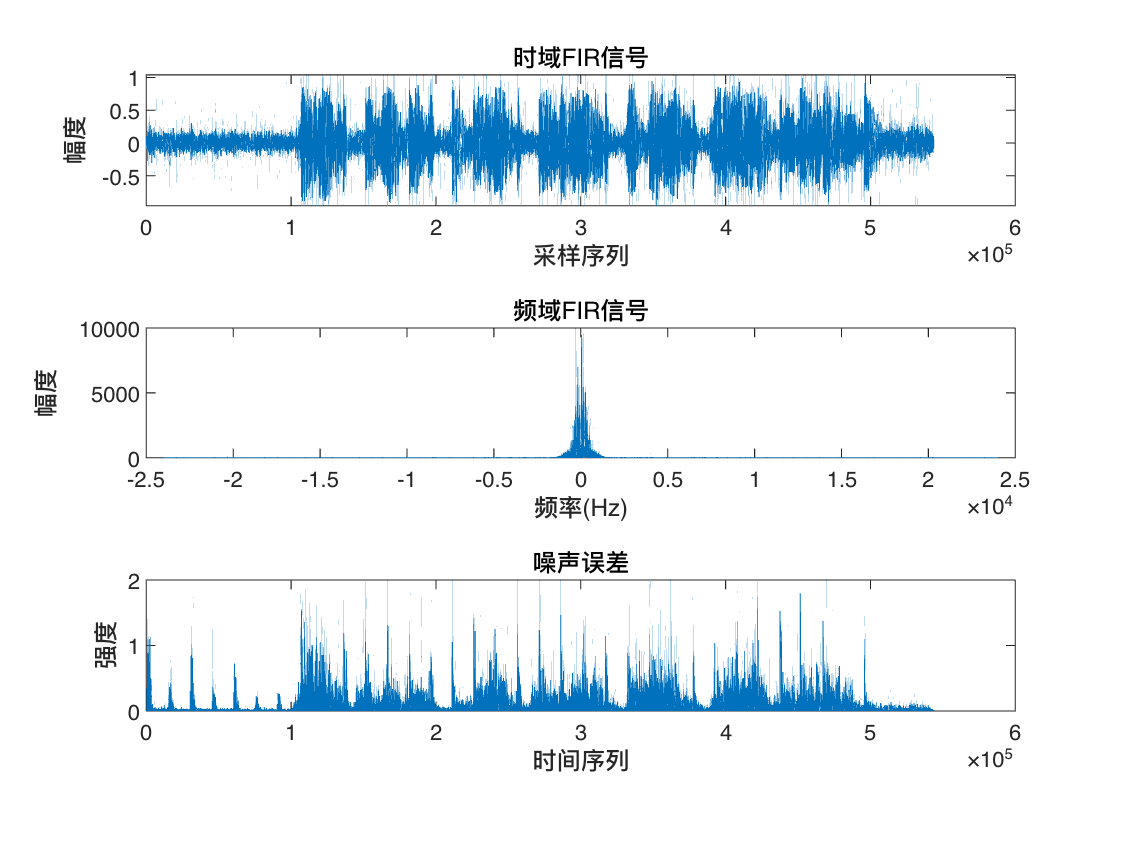

figure("NumberTitle","off","Name","FIR滤波器");
subplot(311);
plot(simulated_fir_filtered_music);
xlabel('采样序列');
ylabel('幅度');
title('时域FIR信号');
subplot(312);
plot(f,abs(fftshift(fft(simulated_fir_filtered_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频域FIR信号");
en_fir_real = (simulated_fir_filtered_music - music) .^ 2;
subplot(313);
plot(en_fir_real);
xlabel("时间序列");
ylabel("强度");
title("噪声误差");

### 2.6.播放效果

% sound(simulated_noise_filtered, 44100);

### 2.7.Kalman滤波

simulated_kalman_filtered_music = kalman_filter(simulated_noise_music, fs, simulated_noise);
en_kalman_simulated = (music - simulated_kalman_filtered_music') .^ 2;

### 2.8.Kalman滤波效果展示

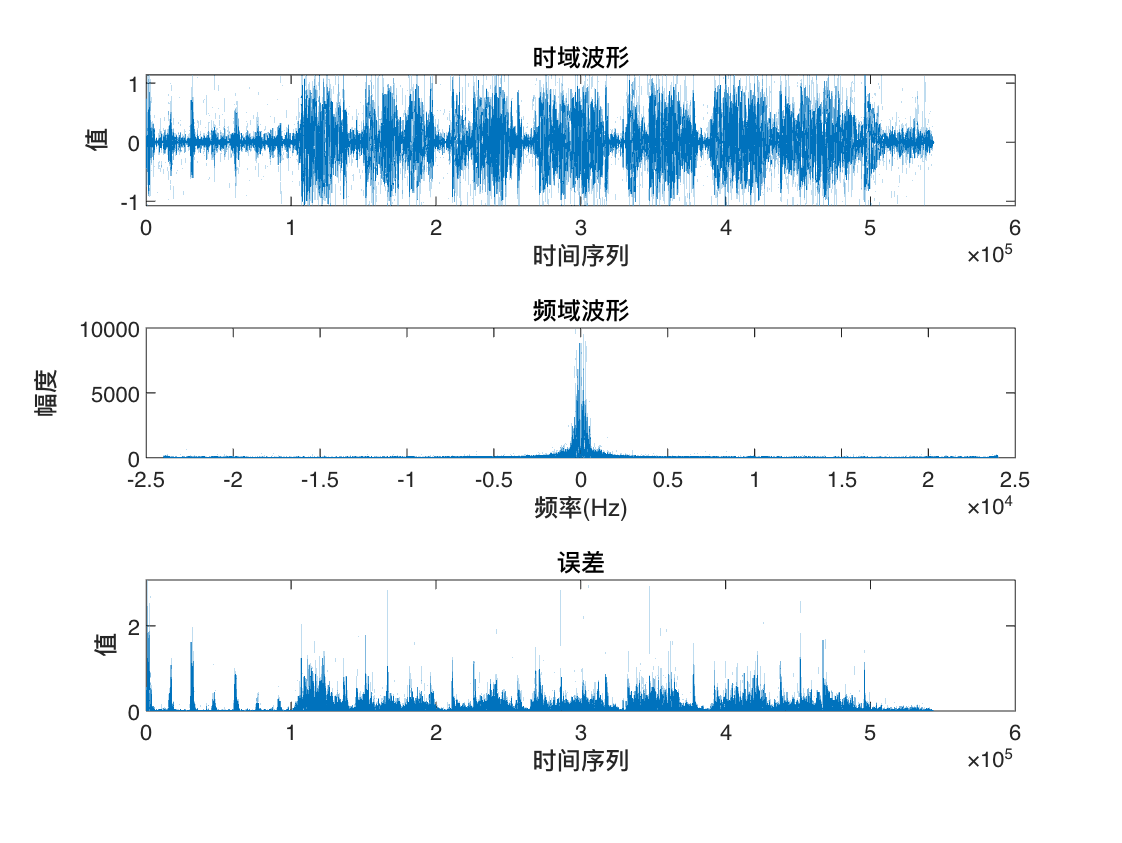

figure("NumberTitle","off","Name","Kalman模拟噪声表现");
subplot(311);
plot(simulated_kalman_filtered_music),title("时域波形");
xlabel("时间序列");
ylabel("值");
subplot(312);
plot(f,abs(fftshift(fft(simulated_kalman_filtered_music)))),title("频域波形");
xlabel("频率(Hz)");
ylabel("幅度");
subplot(313);
n=(1:length(music))';
plot(n,en_kalman_simulated),title('误差');
xlabel("时间序列");
ylabel("值");

### 2.9.LMS滤波

% 将simulated_noise_music作为xn,music作为dn进行滤波;
output_lms_simulated = LMS_Filter(simulated_noise,simulated_noise_music,60,0.0005);
simulated_lms_filtered_music = simulated_noise_music - output_lms_simulated';
en_lms_simulated = (music - simulated_lms_filtered_music).^2;

### 2.10.LMS滤波效果展示

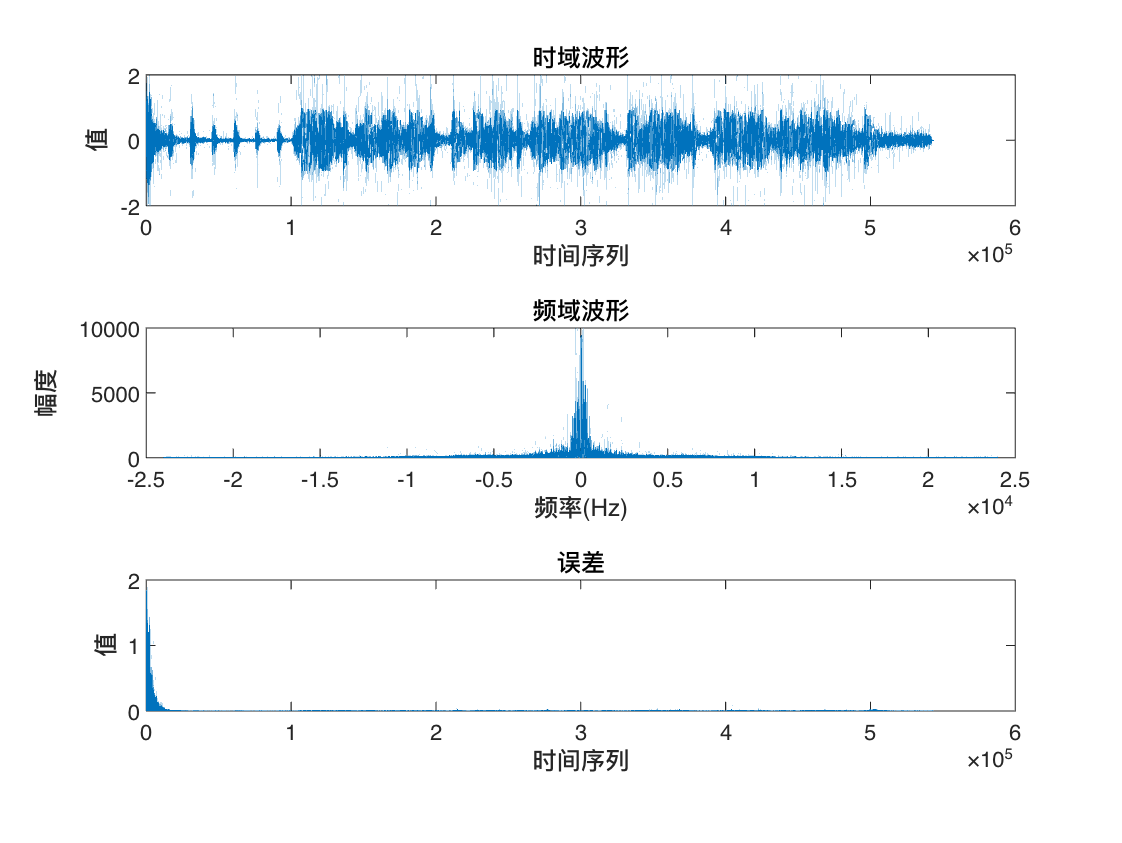

figure("NumberTitle","off","Name","LMS模拟噪声表现");
subplot(311);
plot(simulated_lms_filtered_music),title("时域波形");
xlabel("时间序列");
ylabel("值");
subplot(312);
plot(f,abs(fftshift(fft(simulated_lms_filtered_music)))),title("频域波形");
xlabel("频率(Hz)");
ylabel("幅度");
subplot(313);
n=(1:length(music))';
plot(n,en_lms_simulated),title('误差');
xlabel("时间序列");
ylabel("值");

## 3.实际噪声

### 3.1.读取文件

noisefile = "";
[real_noise, fs] = audioread(noisefile);
real_noise = real_noise(1:543744,:) .* 5;

### 3.2.绘制噪声信号

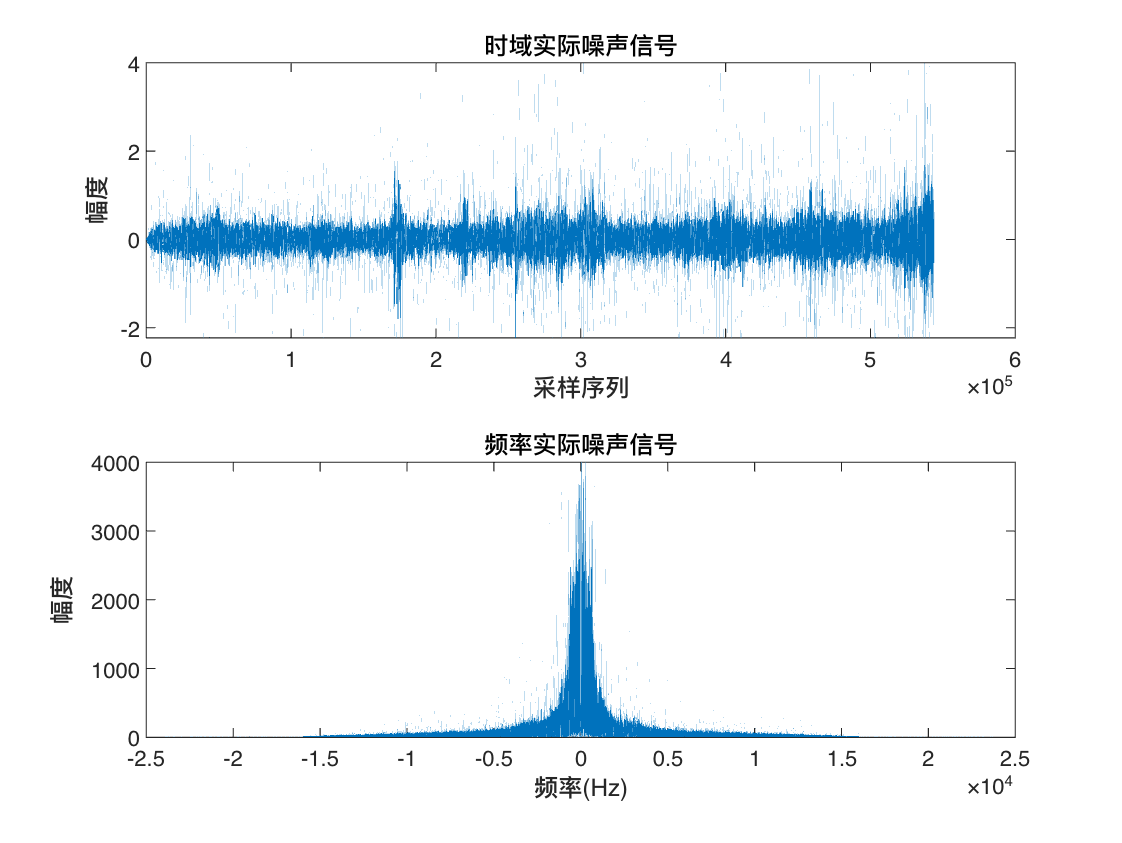

figure("NumberTitle","off","Name","实际噪声");
subplot(211);
plot(real_noise);
xlabel('采样序列');
ylabel('幅度');
title('时域实际噪声信号');
subplot(212);
plot(f,abs(fftshift(fft(real_noise))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频率实际噪声信号");

### 3.3.真实输入信号

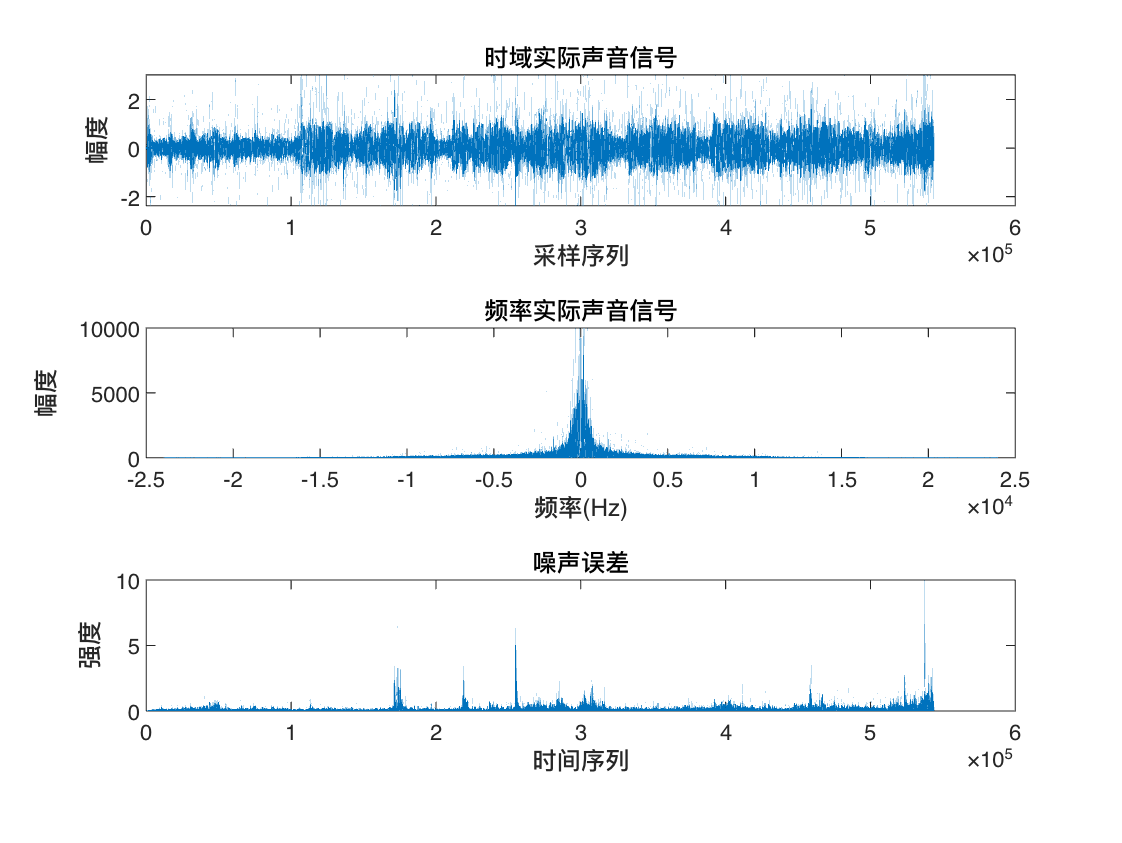

real_noise_music = music + real_noise;
figure("NumberTitle","off","Name","真实输入信号");
subplot(311);
plot(real_noise_music);
xlabel('采样序列');
ylabel('幅度');
title('时域实际声音信号');
subplot(312);
plot(f,abs(fftshift(fft(real_noise_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频率实际声音信号");
subplot(313);
en_noise_real = (real_noise_music - music) .^ 2;
plot(en_noise_real);
xlabel("时间序列");
ylabel("强度");
title("噪声误差");

### 3.4.播放效果

% sound(real_noise_music,44100);

### 3.5.FIR滤波

%% 设计低通滤波器
L = length(real_noise_music);
%% 应用低通滤波器
real_fir_filtered_music = filter(fir_filter, 1, real_noise_music);

### 3.6.FIR滤波器效果展示

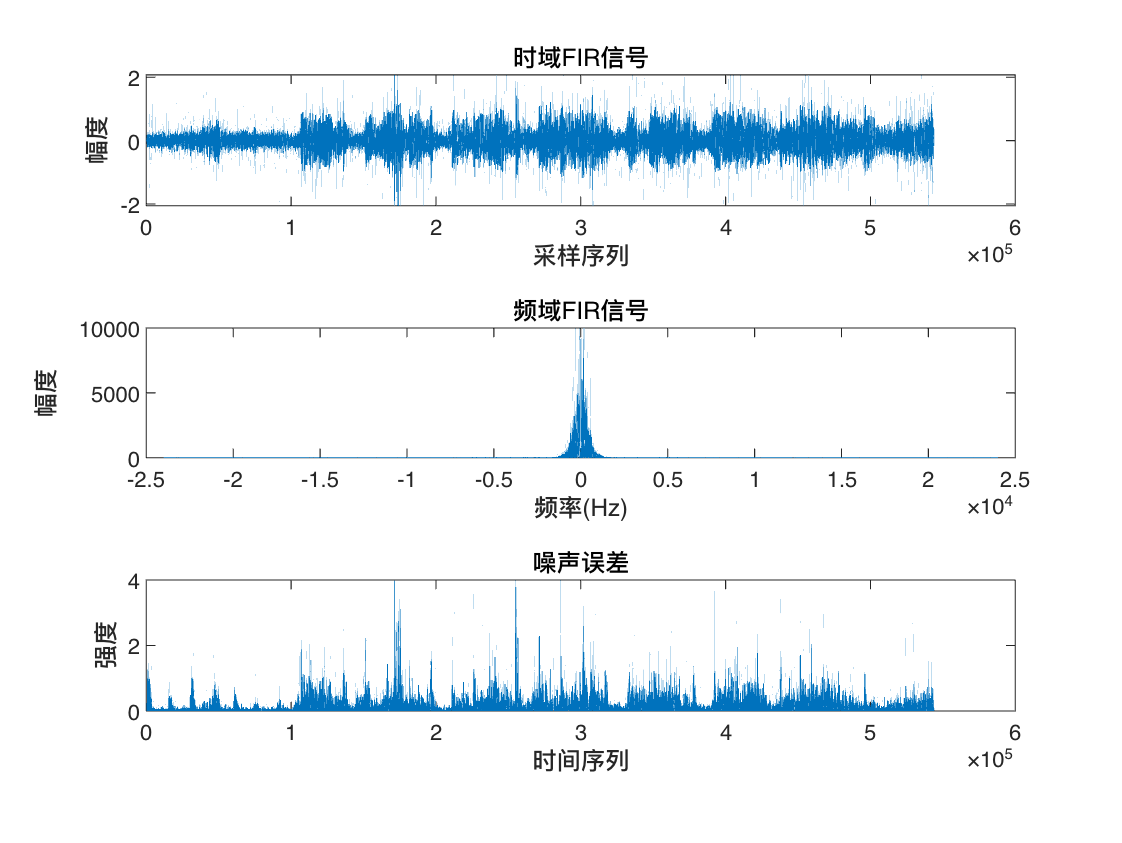

figure("NumberTitle","off","Name","FIR滤波器");
subplot(311);
plot(real_fir_filtered_music);
xlabel('采样序列');
ylabel('幅度');
title('时域FIR信号');
subplot(312);
plot(f,abs(fftshift(fft(real_fir_filtered_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频域FIR信号");
en_fir_real = (real_fir_filtered_music - music) .^ 2;
subplot(313);
plot(en_fir_real);
xlabel("时间序列");
ylabel("强度");
title("噪声误差");

### 3.7.Kalman滤波

output_kalman_real = kalman_filter(real_noise_music,fs,real_noise);
real_kalman_filtered_music = real_noise_music - output_kalman_real';

### 3.8.Kalman滤波效果展示

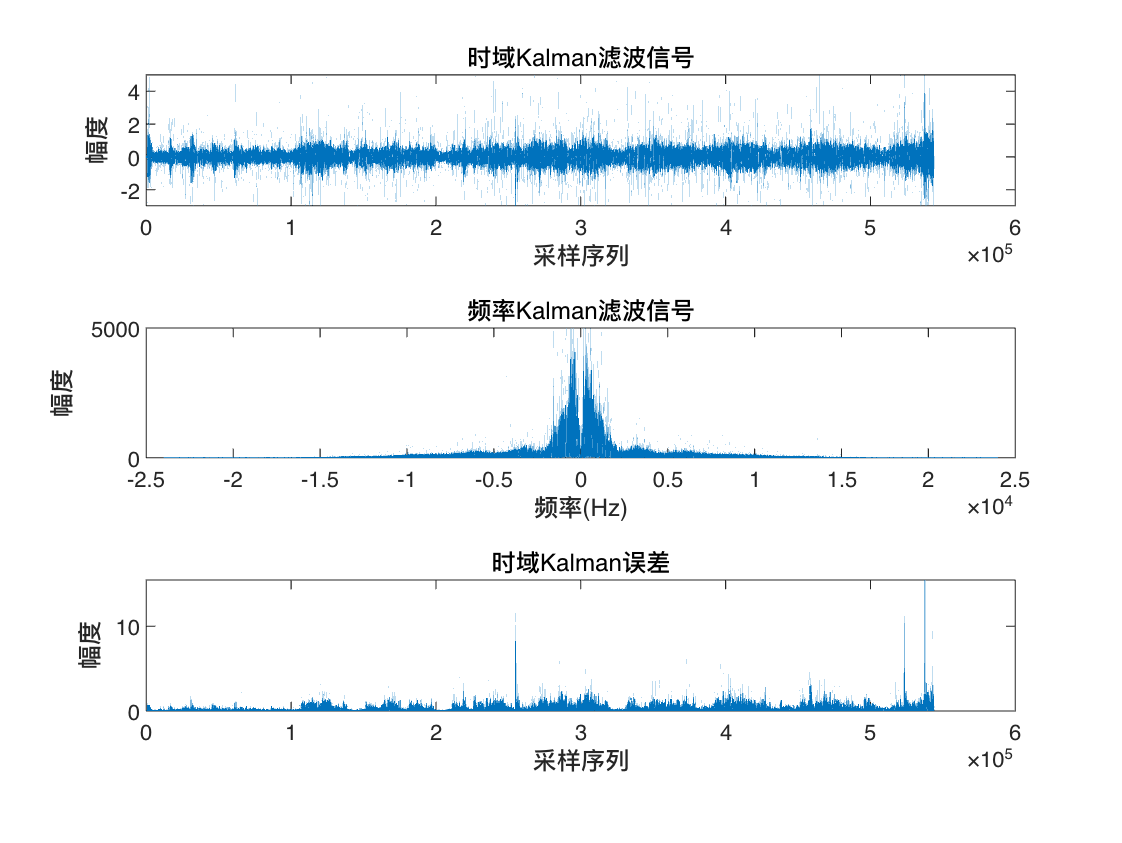

figure("NumberTitle","off","Name","Kalman实际噪声表现");
subplot(311);
plot(real_kalman_filtered_music);
xlabel('采样序列');
ylabel('幅度');
title('时域Kalman滤波信号');
subplot(312);
plot(f,abs(fftshift(fft(real_kalman_filtered_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频率Kalman滤波信号");
en_kalman_real = (music - real_kalman_filtered_music).^2;
subplot(313);
plot(en_kalman_real);
xlabel('采样序列');
ylabel('幅度');
title('时域Kalman误差');

### 3.9.Wiener滤波

output_wiener_real = wiener_filter(real_noise_music);
real_wiener_filtered_music = output_wiener_real;

### 3.10.Wiener滤波效果展示

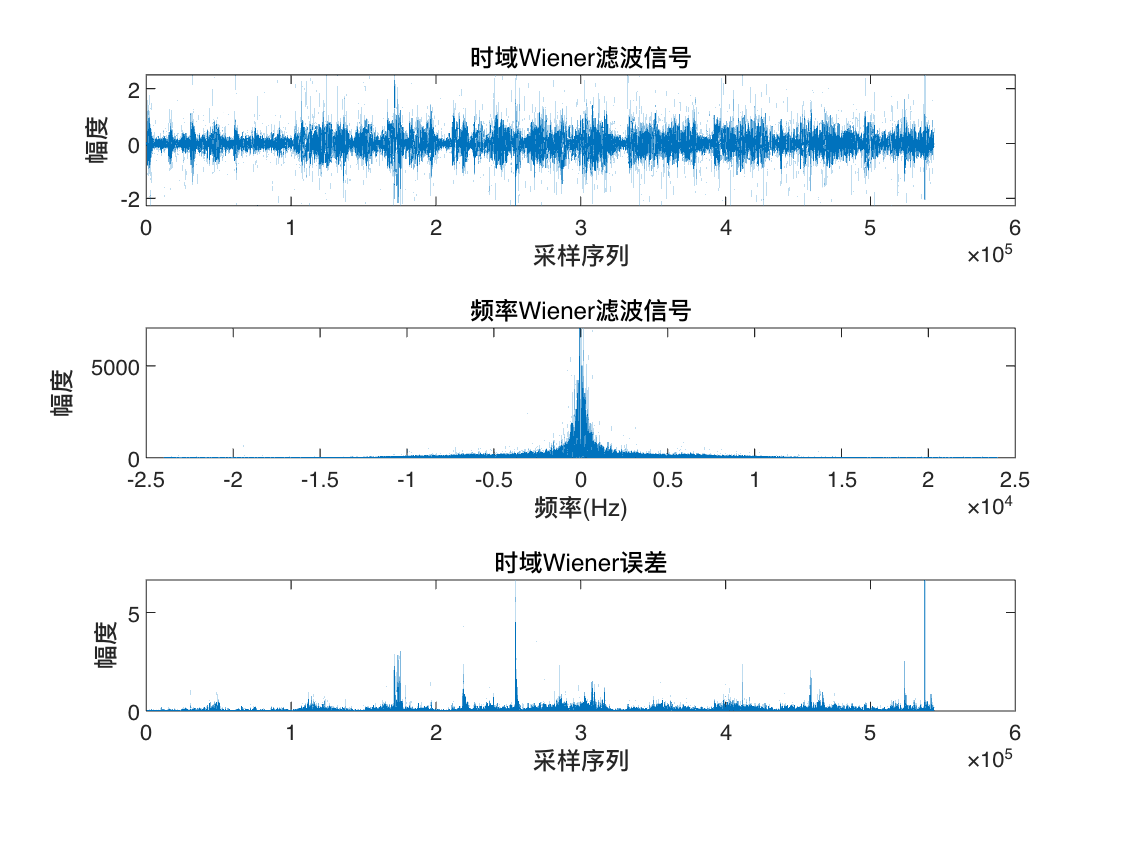

figure("NumberTitle","off","Name","Wiener实际噪声表现");
subplot(311);
plot(real_wiener_filtered_music);
xlabel('采样序列');
ylabel('幅度');
title('时域Wiener滤波信号');
subplot(312);
plot(f,abs(fftshift(fft(real_wiener_filtered_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频率Wiener滤波信号");
en_kalman_real = (music - real_wiener_filtered_music).^2;
subplot(313);
plot(en_kalman_real);
xlabel('采样序列');
ylabel('幅度');
title('时域Wiener误差');

### 3.11.LMS滤波

output_lms_real = LMS_Filter(real_noise,real_noise_music,60,0.0005);
real_lms_filtered_music = real_noise_music - output_lms_real';
en_lms_real = (music - real_lms_filtered_music).^2;

### 3.12.LMS效果展示

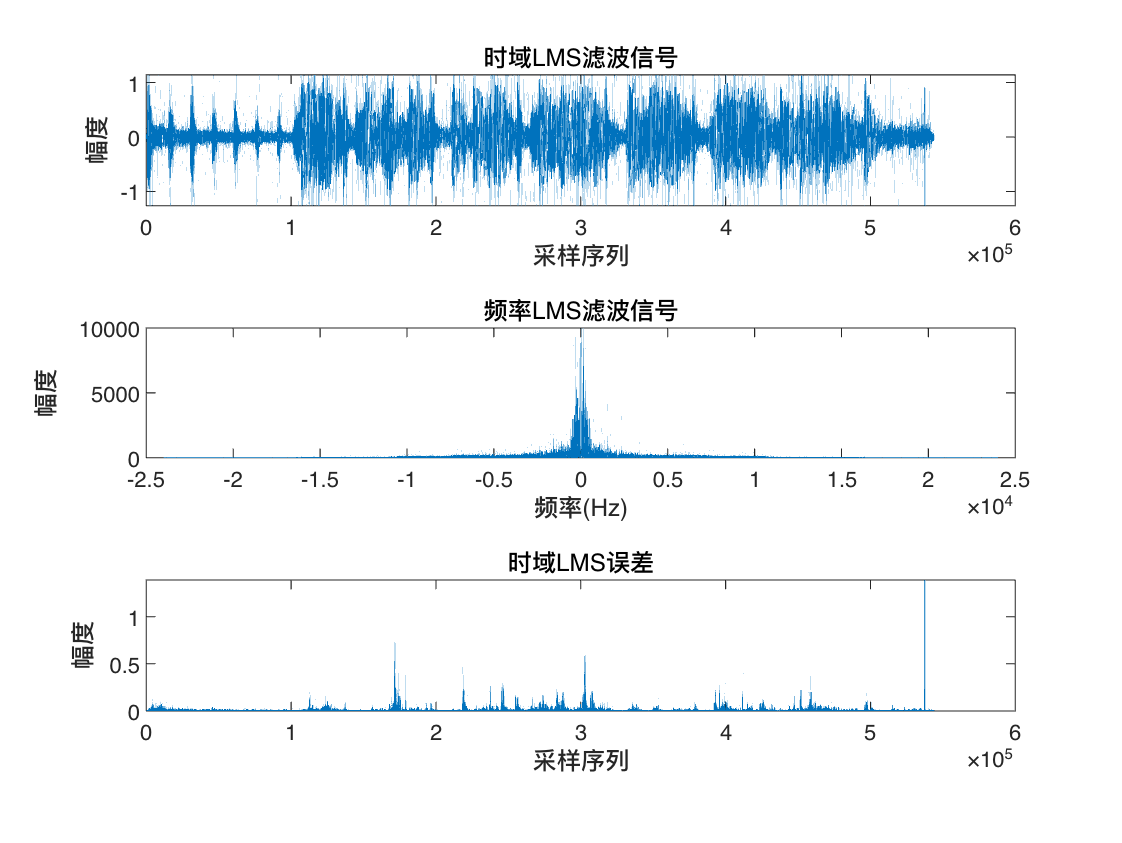

figure("NumberTitle","off","Name","LMS实际噪声表现");
subplot(311);
plot(real_lms_filtered_music);
xlabel('采样序列');
ylabel('幅度');
title('时域LMS滤波信号');
subplot(312);
plot(f,abs(fftshift(fft(real_lms_filtered_music))));
xlabel("频率(Hz)");
ylabel("幅度");
title("频率LMS滤波信号");
subplot(313);
plot(en_lms_real);
xlabel('采样序列');
ylabel('幅度');
title('时域LMS误差');

## 附:构建滤波器

### 1.构建LMS自适应滤波器

function yn = LMS_Filter(xn,dn,M,mu)
% xn:输入信号
% dn:期望信号
% M:滤波器阶数
% mu:收敛因子,即学习率
Length = length(xn);
% 获取xn的长度
yn = zeros(1, Length);
% 滤波器输出
W = zeros(M, 1);
% 权值参数向量矩阵
% M表示滤波器阶数,也称为滤波器的可记忆长度,即:n时刻的输入会受到n-M+1~n时刻输入的影响
for i = M:Length
    X = xn(i:-1:(i-M+1));
    % 可记忆长度,n时刻的输入受到n-M+1~n时刻输入的影响,以这种形式表达
    yn(i) = W' * X; 
    % 计算当前时刻的滤波器输出
    en = dn(i) - yn(i); 
    % 计算dn - yn,计算误差
    W = W + 2 * mu * en * X; 
    % 采用梯度下降法更新W
end
end

### 2.构建Kalman滤波器

function [Output] = kalman_filter(NoisyInput,Fs,Noise)
% 卡尔曼滤波函数

% 基础变量设置
Len_windowT = 0.0025; % 窗长2.5ms
Hop_Percent = 1; % 窗移占比
AR_Order = 20; % 自回归滤波器阶段
Num_Iter = 7; %迭代次数
% [Input, Fs] = audioread('six.wav');
% Input = Input(:,1);
% Noise = normrnd(0,sqrt(0.001),size(Input));
% NoisyInput = Input + Noise;
% Time = (0:1/Fs:(length(Input)-1)/Fs)';

%分帧加窗处理
Len_WinFrame = fix(Len_windowT * Fs);
Window = ones(Len_WinFrame,1);
[Frame_Signal, Num_Frame] = KFrame(NoisyInput, Len_WinFrame, Window, Hop_Percent);

%初始化
H = [zeros(1,AR_Order-1),1];   % 观测矩阵
R = var(Noise);     % 噪声方差
[FiltCoeff, Q] = lpc(Frame_Signal, AR_Order);   % LPC预测，得到滤波器的系数
P = R * eye(AR_Order,AR_Order);   % 误差协方差矩阵
Output = zeros(1,size(NoisyInput,1));   % 输出信号
Output(1:AR_Order) = NoisyInput(1:AR_Order,1)';   %初始化输出信号
OutputP = NoisyInput(1:AR_Order,1);

% 迭代器的次数.
i = AR_Order+1;
j = AR_Order+1;

%进行卡尔曼滤波
for k = 1:Num_Frame   %一次处理一帧信号
    jStart = j;     %跟踪每次迭代AR_Order+1的值.
    OutputOld = OutputP;    %为每次迭代保留第一批AROrder预估量
    
    for l = 1:Num_Iter
        A = [zeros(AR_Order-1,1) eye(AR_Order-1); fliplr(-FiltCoeff(k,2:end))];
        
        for ii = i:Len_WinFrame
            %Kalman滤波基本方程式
            OutputC = A * OutputP;
            Pc = (A * P * A') + (H' * Q(k) * H);
            K = (Pc * H')/((H * Pc * H') + R);
            OutputP = OutputC + (K * (Frame_Signal(ii,k) - (H*OutputC)));
            Output(j-AR_Order+1:j) = OutputP';
            P = (eye(AR_Order) - K * H) * Pc;
            j = j+1;
        end       
        i = 1;
        if l < Num_Iter
            j = jStart;
            OutputP = OutputOld;
        end     
        % 更新滤波后信号的lpc
        [FiltCoeff(k,:), Q(k)] = lpc(Output((k-1)*Len_WinFrame+1:k*Len_WinFrame),AR_Order);
    end
end
end

### 3.构建Wiener滤波器

function [wiener_enspeech] = wiener_filter(testsignal)
%维纳滤波器函数
testsignal=testsignal';
frame_len=256; %帧长
step_len=0.5*frame_len; %分帧时的步长，相当于重叠50%
wav_length=length(testsignal);
R = step_len;
L = frame_len; 
f = (wav_length-mod(wav_length,frame_len))/frame_len;
k = 2*f-1; % 帧数
 h = sqrt(1/101.3434)*hamming(256)'; % 汉宁窗乘以系数的原因是使其复合条件要求；
% testsignal = testsignal(1:f*L);  % 带噪语音与纯净语音长度对齐
% signal= signal(1:f*L);  
win = zeros(1,f*L); % 设定初始值；
wiener_enspeech = zeros(1,f*L);                         
%-------------------------------分帧-------------------------------------
for r = 1:k 
    y = testsignal(1+(r-1)*R:L+(r-1)*R); % 对带噪语音帧间重叠一半取值；
    y = y.*h; % 对取得的每一帧都加窗处理；
    w = fft(y); % 对每一帧都作傅里叶变换；
    Y(1+(r-1)*L:r*L) = w(1:L); % 把傅里叶变换值放在Y中；
end
%-------------------------------估计噪声-----------------------------------
   NOISE= stationary_noise_evaluate(Y,L,k); %噪声最小值跟踪算法
 % 每帧中的傅里叶变换和噪声估计均如上所示
 %-------------------------------winner-------------------------------------
for t = 1:k     
    X = abs(Y).^2;   
    S=max((X(1+(t-1)*L:t*L)-NOISE(1+(t-1)*L:t*L)),0);
    G_k=(X(1+(t-1)*L:t*L)-NOISE(1+(t-1)*L:t*L))./X(1+(t-1)*L:t*L);
    S = sqrt(S);
    A1=G_k.*S;
    A = Y(1+(t-1)*L:t*L)./abs(Y(1+(t-1)*L:t*L)); % 带噪于语音的相位；
    S = A1.*A; % 因为人耳对相位的感觉不明显，所以恢复时用的是带噪语音的相位信息；
    s = ifft(S);   
    s = real(s); % 取实部；
    wiener_enspeech(1+(t-1)*L/2:L+(t-1)*L/2) = wiener_enspeech(1+(t-1)*L/2:L+(t-1)*L/2)+s; % 在实域叠接相加；
    win(1+(t-1)*L/2:L+(t-1)*L/2) = win(1+(t-1)*L/2:L+(t-1)*L/2)+h; % 窗的叠接相加；
end
wiener_enspeech = wiener_enspeech./win; % 去除加窗引起的增益得到增强的语音；
wiener_enspeech=wiener_enspeech';
end